# Exercise 3

## Roots and Branches

### About This Exercise

What does a seed do to become a tree? It has no map of the soil and the sky, just the ability to grow and sense the environment. It explores with its roots and branches, favoring directions that give it more of what it needs. If a root hits an obstacle, it will change its direction of growth.

We can do motion planning in a similar way, where we are given a seed and some idea that we're getting closer to the goal as well as the ability to sense when we are within an obstacle. In this exercise, you will create a function to create what is called a rapidly-exploring random tree that starts from a seed and grows until it hits the goal. You will generate a path without needing a roadmap covering the entire space!

**By the end of this exercise, you'll be able to: **

- **Create a probabalistic roadmap using the Rapidly-Exploring Random Tree algorithm.**

### RRT - Rapidly-Exploring Random Tree

[► Complete the RRT function](matlab:open('./RRT.mlx')), which takes in obstacles, a start point, and a goal point, and returns a series of waypoints to get from the start to the goal.

Again, we need to set up the coordinate of the obstacles. We'll create a polyvec out of the obstacles as input into the RRT function.

lim = 4;
p1x = [-2  -1 1 2 1 -1];
p1y = [0 1 1 0 -1 -1]-1;
p2x = [-2 0 .5 -1];
p2y = [3 3 2 2];

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;

polyvec = makePolyvec(obstacle);

Specify the inputs to RRT and then run RRT.

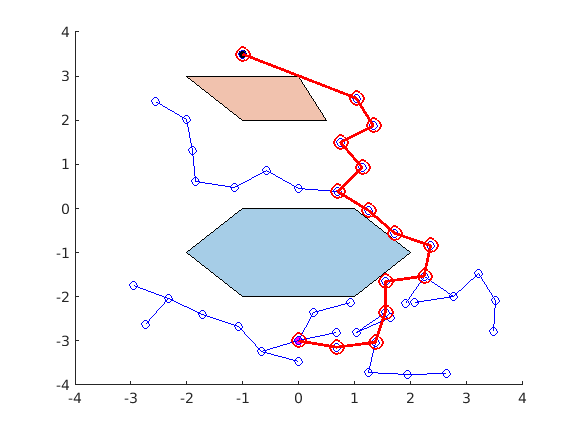

start = [-0, -3];
goal = [-1, 3.5];
dq = 0.7;
N = 500;
plotflag = 1;
nodes_xy = RRT(start, goal, polyvec, lim, N, dq, plotflag);

### Finished!

With this simple algorthim, you now have a fast method of finding paths between points not only for 2D robots, but also manipulators that can have 6 degrees of freedom or more. All that is needed is a function to test whether a point is in collision with an obstacle. Of course, there are some limitations, as paths found are not optimal and you may not find always find a path even if one exists. In the next exercise, you will make some adjustments to the algorithm to improve it.